## How to Manipulate a Faust

This livescript is intended to gently introduce the operations available to manipulate a Faust object. It comes after the first livescript (available [here](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/Faust_creation.mlx) for download or [here](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/Faust_creation.html) as a web page), so it's assumed you already know how to create a Faust object from one way or another.

Keep in mind that a full API doc is available [here](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/namespacematfaust.html) every time you need details. In particular the Faust class is documented [here](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html).

**NOTE**: the livescript is made to be executed sequentially, otherwise, skipping some cells, you would end up on an import error.

### Table of Contents:

1. Getting Basic Information about a Faust Object

1.1 Obtaining Dimension and Scalar Type Information

1.2 Obtaining Other Faust Specific Information

1.3 Plotting a Faust

1.4 About Sparsity!

2. Faust Algebra and other Operations

2.1 Transpose, conjugate, transconjugate

2.2 Add, Subtract and Multiply

2.3 Faust Multiplication by a Vector or a Matrix

2.4 Faust Norms

2.5 Faust Normalizations

2.6 Faust Concatenation

2.7 Faust Indexing and Slicing

### 1. Getting Basic Information about a Faust Object

First of all, given any object, you might ask yourself if it's a Faust or not (typically when you receive an object in a function, matlab being built on dynamic types, you can't say for sure it's a Faust). [Faust.isFaust()](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#ac5d5fbe66ef212a1c7043b78504f87fc) is the function to verify an object is a Faust. Its use is straighforward as you can see in the documentation. Note by the way, that a more accessible alias is available at the package root `(matfaust.isFaust`).

### 1.1 Obtaining Dimension and Scalar Type Information

Firstly, let's list basic Faust informative methods/attributes you're probably used to for matlab matrices:

- [size](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#a7146c7de95b35efc570a377765edda27),

- [numel](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#af62f554cd8b491a2c75ee06019f87d8a),

- [isreal](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#a7527e1fda21bc1678646a4b40db28eb6).

To keep it really clear, let's show some examples operated on a random Faust.

F = matfaust.rand(5,10)
size(F)
numel(F)
isreal(F)

If the attributes printed out above seem not clear to you, you're probably not a Matlab user. Anyway you'll find all descriptive informations in the FAµST API documentation (see the links above).

As a complement, you can also refer to the Matlab API documentation:

- [size](https://www.mathworks.com/help/matlab/ref/size.html)

- [numel](https://www.mathworks.com/help/matlab/ref/numel.html)

- [isreal](https://www.mathworks.com/help/matlab/ref/isreal.html)

About size, it's noteworthy that contrary to what Matlab is capable of on an array, you cannot [reshape](https://www.mathworks.com/help/matlab/ref/reshape.html) a Faust.

### 1.2 Obtaining Other Faust Specific Information

As you've seen in this livescript and the first one, when you print a Faust object, several pieces of information appear. Most of them are also available independently with specific functions.

For instance, if you want information about factors, nothing is more simple than calling directly the next functions:

- [numfactors()](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#a5e77419460592366457aa60175472e2e) ; which gives you the number of factors (aka layers) a Faust object is composed of.

- [factors()](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#a65a84416b4b1fd050654a02232e95d2f) ; which allows you to copy any of the Faust's factors givens its index.

Going back to our F object, let's call these functions:

numfactors(F)

For example, try to copy the third factor:

f3 = factors(F, 3)

Note that, since Faust 2.3, the function doesn't alterate the factor format. If the Faust object contains a sparse factor then you'll receive a sparse matrix.

Since Faust 2.3 again, it's possible to retrieve a sub-sequence of Faust factors.

Go straight to the example, extracting factors from F:

factors(F, 3:4)

Hmm... something is different from the previous example. We indeed received a Faust as return type, great! You've just learned another way to create a Faust from another, additionally to what you've seen in the first [livescript](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/Faust_manipulation.html).

Without this function, you'd surely have written something similar to:

import matfaust.Faust
Faust({factors(F, 3), factors(F, 4)})

OK, that's not awful but I let you imagine how much complicated it is with more factors.

### 1.3 Plotting a Faust

Available soon!

### 1.4 About Sparsity!

Three functions of the Faust class are here to evaluate the sparsity of a Faust object.

Let's call the first one:

nnz_sum(F)

I'm sure you guessed exactly what the function returns, if you doubt it, here is the doc: [Faust.nnz_sum()](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#a7dc7f3cb86b02b3c2cd725387c34300d). The smaller `nnz_sum`, the sparser the Faust.

Next comes the function: [Faust.density()](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#ac33ff53bbff16f93666acec05031511b).

This function along with its reciprocal [Faust.rcg()](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#aff3261319b63c49d51a699726edc74bc) can give you a big hint on how much your Faust is potentially optimized both for storage and calculation. The sparser the Faust, the larger the Relative Complexity Gain (RCG)!

density(F)
rcg(F)

According to its RCG, this Faust doesn't seem to be of any help for optimization but look at the graphic the next script generates:

nfactors = 3;
startd = 0.01;
endd = 1;
dim_sz = 1000;
ntests = 10;
sizes = zeros(ntests, 1);
rcs = zeros(ntests, 1);
densities = linspace(startd, endd, ntests);
for i=1:ntests
   d = densities(i);
   F = matfaust.rand(dim_sz, dim_sz, 'num_factors', nfactors, 'density', d, 'fac_type', 'sparse');
   sizes(i) = nbytes(F);
   rcs(i) = density(F);
end
plot(rcs, sizes)
legend('size')
xlabel('Density')
ylabel('Faust Size (bytes)')

Isn't it obvious now that the smaller the density the better?! Indeed, for two Faust objects of the same shape and the same number of factors, a smaller density (linearly) implies a smaller file size for storage. This point applies also to the memory (RAM) space to work on a Faust.

We'll see later how the computation can benefit of a bigger RCG (or smaller density). But let's point out right now that the sparsity is often a tradeoff with accuracy, as the following plot shows about the truncated SVD of a matrix $M \in {\mathbb R}^{512 \times 512$. Note beforehand that the SVD of M (truncated or not) can be seen as a Faust which approximates M.

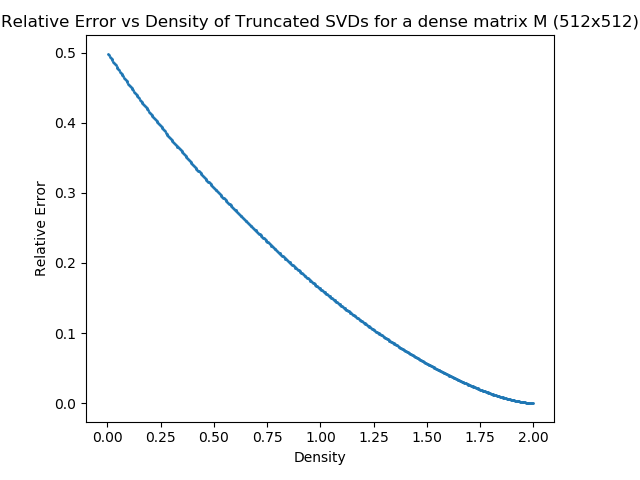

Here is the script to reproduce the last figure with pyfaust: [test_svd_rc_vs_err.py](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/test_svd_rc_vs_err.py)

### 2. Faust Algebra and other Operations

In order to write some nice algorithms using Faust objects, you'll have to use the basic "stable" operations a Faust is capable of. Let's make a tour of them.

#### 2.1 Transpose, conjugate, transconjugate

- [Faust.transpose](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#a029a3db751ae1282eca2af94ce4101ec) or [.'](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#a029a3db751ae1282eca2af94ce4101ec)

- [Faust.conj](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#aec9036a3d251fd47038a9a338b91502d),

- [Faust.ctranspose](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#a66c1abdcbcfe8505457ce69a7b355716) or ['](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#a66c1abdcbcfe8505457ce69a7b355716)

You are probably familiar with .' and ' shorthand operators from Matlab. Well, they are also used in the Faust class.

G = matfaust.rand(10, 15, 'dim_sizes', [10,15], 'field', 'complex')
G.'
conj(G)
G'

What really matters here is that the results of G.', conj(G) and G' are all Faust objects. Behind the scene, there is just one memory zone allocated to the factors. Strictly speaking they are memory views shared between G, G.' and G'. So don't hesitate to use!

#### 2.2 Add, Subtract and Multiply

s = size(G, 1);
F = matfaust.rand(s, s);
G = matfaust.rand(s, s, 'field', 'complex');
F+G

Go ahead and verify it's accurate.

norm(full(F+G)-(full(F)+full(G)), 'fro')

Some points are noticeable here:

- F is real but G is complex. The Faust API is able to return the proper type for the resulting Faust, that is a complex Faust.

- F+G is composed of 8 factors, however F and G are both 5 factors long. It's due to the way the addition is implemented (Faust concatenation is hiding behind).

Subtracting is not different:

F-G

You can also add/subtract scalars to Faust objects.

F+2

Note that here again `numfactors(F+2) ~= numfactors(F)`.

The FAµST API supports equally the Faust to array addition and subtraction.

F+full(F)
F-full(F)
all(all(full(F-full(F)) < eps))

Now let's multiply these Fausts!

FG = F*G
norm(full(FG)-full(F)*full(G))/norm(full(F)*full(G))

Faust scalar multiplication is also available and here again the result is a Faust object!

F*2

#### 2.3 Faust Multiplication by a Vector or a Matrix

When you multiply a Faust by a vector or a matrix (the number of nrows must match the number of Faust columns), you'll get respectively a vector or a matrix as result.

vec = rand(size(F, 2), 1);
F*vec

Let's launch a timer to compare the execution times of Faust-vector multiplication and Faust's dense matrix-vector multiplication.

F_times_vec = @() F*vec
FD = full(F);
FD_times_vec = @() FD*vec
timeit(F_times_vec)
timeit(FD_times_vec)
all(all(F*vec-FD*vec < 1e-7))
rcg(F)

When the RCG is lower than 1 the Faust-vector multiplication is slower. Making a random Faust with a large RCG (small density) shows better results.

G = matfaust.rand(1024, 1024, 'num_factors', 3, 'density', .001, 'fac_type', 'sparse')
GD = full(G);
vec2 = rand(1024, 1);
timeit(@() G*vec2)
timeit(@() GD*vec2)
rcg(G)

It goes without saying that a big RCG gives a big speedup to the Faust-vector multiplication relatively to the corresponding (dense) matrix-vector multiplication. I hope the example above has finished to convince you.

Just to convince you as well of the Faust-vector multiplication accuracy:

norm(G*vec2 - GD*vec2)

What applies to Faust-vector multiplication remains valid about Faust-matrix multiplication. Take a look:

M = rand(1024,32);
timeit(@() G*M)
timeit(@() GD*M)
norm(GD*M-G*M)/norm(GD*M)

Well, what do we see? A quicker Faust-matrix multiplication than the matrix-matrix corresponding multiplication, though a good accuracy of the Faust-matrix multiplication is also clearly confirmed.

These examples are somehow theoretical because we cherry-pick the Faust to ensure that the RCG is good to accelerate the muplication, but at least it shows the potential speedup using Faust objects.

#### 2.4 Faust Norms

The Faust class provides a norm function which handles different types of norms. This function is really close to Matlab [norm](https://www.mathworks.com/help/matlab/ref/norm.htm) function.

In the following example, three of the four norms available are computed.

norm(F,1)
norm(F, inf)
norm(F, 'fro')
norm(full(F), 1)
norm(full(F), inf)
norm(full(F), 'fro')

Perfect! But a last norm is available, this is the Faust's 2-norm. Let's see in the next small benchmark how the Faust 2-norm is being computed faster than the Faust's dense matrix 2-norm.

timeit(@() norm(G, 2))
timeit(@() norm(GD, 2))

The power-iteration algorithm implemented in the FAµ?ST C++ core is faster on G and the relative error is not bad too. The norm computation is faster as it benefits from faster Faust-vector multiplication.

err = abs((norm(G, 2)-norm(GD,2))/norm(GD,2))

#### 2.5 Faust Normalizations

The FAµST API proposes a group of normalizations. They correspond to the norms available and discussed above.

It's possible to normalize along columns or rows with any type of these norms.

F = matfaust.rand(5, 10)
NF = normalize(F)

The API doc is [here](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/classmatfaust_1_1Faust.html#abb16b52adc84eadc2835ae0542f75b90).

What's interesting here is the fact that Faust.normalize returns a Faust object. Combined with slicing (that you will see soon), normalize is useful to write algorithms such as Orthonormal Matching Pursuit (OMP), which require matrices with L2-normalized columns, in a way that makes them able to leverage the acceleration offered by the FAµST API.

The normalization coded in C++ is memory optimized (it never builds the dense matrix full(F) to compute the norms of the columns/rows). In the same goal the factors composing the Faust object NF are not duplicated in memory from same factors F, they're used as is with an additional factor giving the appropriate scaling.

factors(NF, 5)

cumerr = 0;
fullF = full(F);
for i=1:size(F,2)
        normalized_col = fullF(:,i)/norm(fullF(:,i));
	cumerr = cumerr + norm(NF(:,i) - normalized_col, 'fro');
end
cumerr

And as you see it works!

#### 2.6 Faust Concatenation

You're probably aware of Matlab arrays concatenation otherwise look this example.

M = rand(5,5);
I = eye(5,5);
[ M; I ]

% it was vertical concatenation, now let's concatenate horizontally
[ M I ]

I'm sure you guessed that likewise you can concatenate Faust objects. That's right!

[ F ; F]

C = [ F F ]
full(C) - [ full(F) full(F) ]

The difference of the two concatenations is full of zeros, so of course it works!

As you noticed the Faust concatenation is stable, you give two Fausts and you get a Faust again. Besides, it's possible to concatenate an arbitrary number of Faust objects.

[F C C F ]

As an exercise, you can write the factors of the Faust` [F ; F]`, F being any Faust.

**Hint**: the block-diagonal matrices are around here.

#### 2.7 Faust Indexing and Slicing

Sometimes you need to access the dense matrix corresponding to a Faust or an element of it (by the way, note that it's costly).

Let's access a Faust item:

F(3, 4)

Why is it costly? Because it essentially converts the Faust to its dense form (modulo some optimizations) to just access one item.

timeit(@() F(3, 4))
timeit(@() FD(3, 4))

It's totally the same syntax as Matlab but much slower so use it with care.

The more advanced slicing operation uses also the same syntax as Matlab:

F(3:5, 4:10)

Here again, the result is another Faust. But this is not a full copy, it makes profit of memory views implemented behind in C++. Solely the first and last factors of the sliced Faust are new in memory, the others are just referenced from the initial Faust F. So use it with no worry for a Faust with a lot of factors!

The Matlab indexing by arbitrary vector of integers has also been implemented in the FAµ?ST C++ core, let's try it:

I = [2, 4, 3];
FI = F(I,:);
matfaust.isFaust(FI)

Again, it's a Faust but is it really working? Verify!

FID = full(FI)
FD = full(F)
all(all(FID(1, :) == FD(I(1), :) & FID(2, :) == FD(I(2), :) & FID(3, :) == FD(I(3), :)))

Yes it is!

This is the notebook's end, you have now a global view of what the Faust class is able and what kind of high-level algorithms it is ready for. You might be interested to read other notebooks, just go back to the [page](https://faustgrp.gitlabpages.inria.fr/faust/last-doc/html/index.html) where you got this one.

**Note:** this livescript was executed using the following matfaust version:

matfaust.version()
